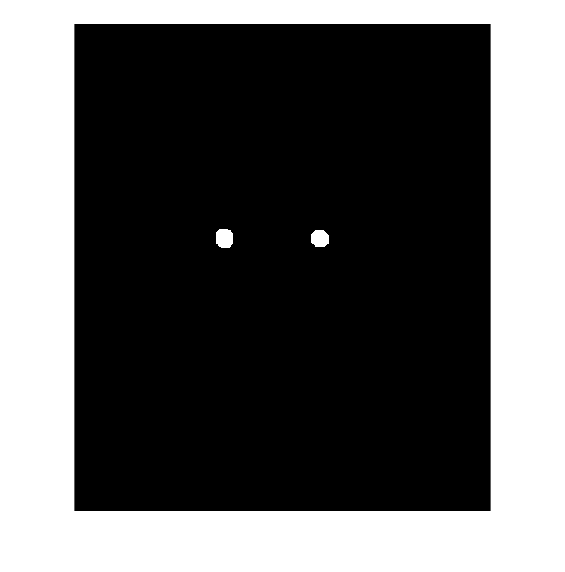

clear
% Read img file
img = imread("../db/DB0/db0_4.jpg");
img1 = double(img);

% Normalize colors
img_gw = gray_world(img);

% Create facemask 
face_mask = facemask(img_gw);
% imshow(face_mask)

%Find eyes and a mouth
eyes = eyemap(img_gw);
% imshow(eyes)
eye_mask = eyemask(eyes);
imshow(eye_mask & face_mask);

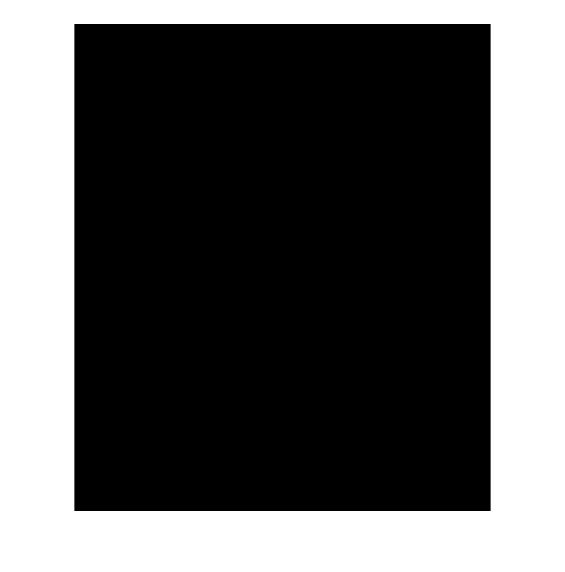


mouth = mouth_map(img_gw);
% imshow(mouth)
mouth_mask = mouthmask(mouth);
imshow(mouth_mask & face_mask)